# 数字图像处理 作业1 (3/4)

阮泉源 201930033629 第一章

## 1.同时对比度实验

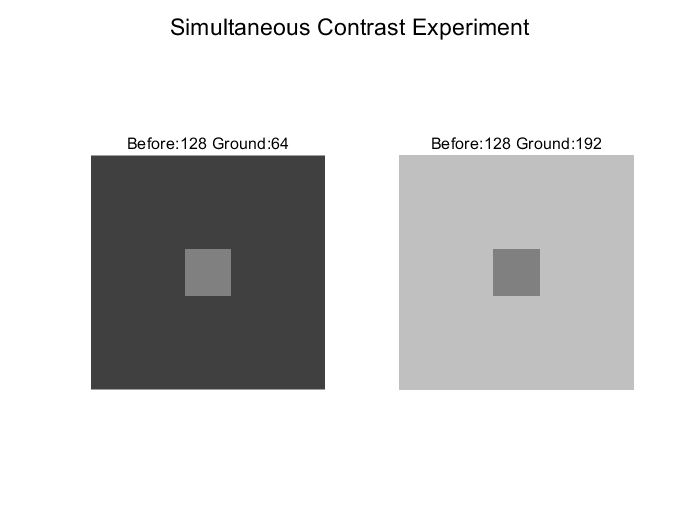

clear; close all;clc;

N=5;k=1;

figure;

before1= 128;ground1=64;
img1 = uint8(ground1*ones(N,N));
img1(ceil(N/2)-floor(k/2):ceil(N/2)+floor(k/2),ceil(N/2)-floor(k/2):ceil(N/2)+floor(k/2)) = before1;
subplot(1,2,1);
imshow(img1);
title(sprintf("Before:%d Ground:%d",before1,ground1))

before2= 128;ground2=192;
img2 = uint8(ground2*ones(N,N));
img2(ceil(N/2)-floor(k/2):ceil(N/2)+floor(k/2),ceil(N/2)-floor(k/2):ceil(N/2)+floor(k/2)) = before2;
subplot(1,2,2);
imshow(img2);
title(sprintf("Before:%d Ground:%d",before2,ground2))

suptitle('Simultaneous Contrast Experiment')

结果分析：

    在相同亮度的刺激下，由于背景亮度不同，人眼看到的主观亮度也不同。

## 2.空间分辨率实验

    dpi是指Dots Per Inch,假设图片大小不变，通过下采样的方式能够改变图片的dpi。

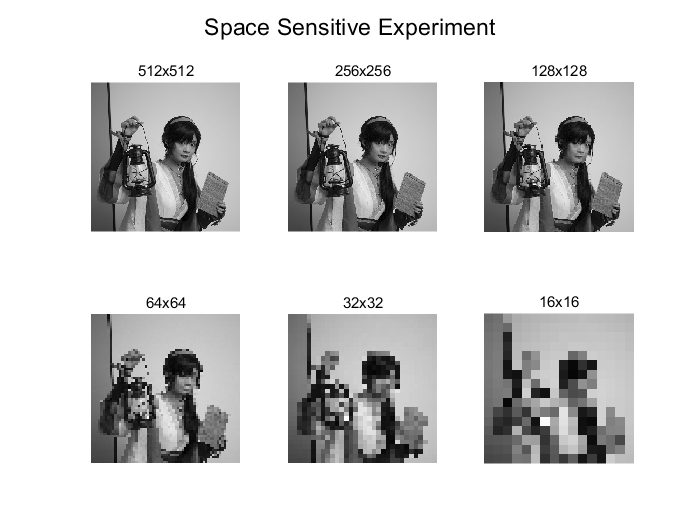

clear; close all;clc;

img_coser = imread('coser.jpg');

img_coser = rgb2gray(img_coser);

figure;

subplot(2,3,1);
imshow(img_coser)
title('512x512')

[w,h] = size(img_coser);

img2 = img_coser(1:2:w,1:2:h);
subplot(2,3,2);
imshow(img2)
title('256x256')

img3 = img_coser(1:4:w,1:4:h);
subplot(2,3,3);
imshow(img3)
title('128x128')

img4 = img_coser(1:8:w,1:8:h);
subplot(2,3,4);
imshow(img4)
title('64x64')

img5 = img_coser(1:16:w,1:16:h);
subplot(2,3,5);
imshow(img5)
title('32x32')

img6 = img_coser(1:32:w,1:32:h);
subplot(2,3,6);
imshow(img6)
title('16x16')

suptitle('Space Sensitive Experiment')

结果分析：

    可以通过均值下采样的方式来获得底空间分辨率的图像。

    空间分辨率越低，图像越模糊。

## 3. 幅度分辨率实验

    图片是包含8位二进制数的数组，通过屏蔽低位数据可以得到不同空间分辨率的图片。

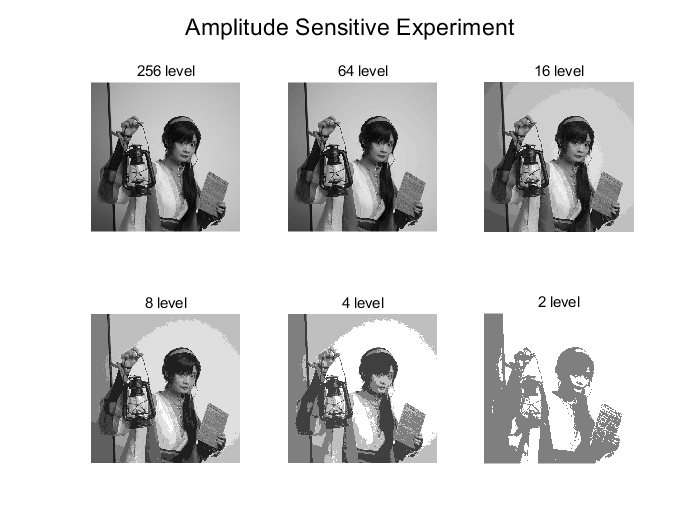

clear; close all;clc;

img_coser = imread('coser.jpg');

img_coser = rgb2gray(img_coser);

figure;

subplot(2,3,1);
imshow(img_coser)
title('256 level')

% 复位法
% 清空低位数据
img2 = bitor(img_coser, 3);
subplot(2,3,2);
imshow(img2)
title('64 level')

img3 = bitor(img_coser, 15);
subplot(2,3,3);
imshow(img3)
title('16 level')

img4 = bitor(img_coser, 31);
subplot(2,3,4);
imshow(img4)
title('8 level')

img5 = bitor(img_coser, 63);
subplot(2,3,5);
imshow(img5)
title('4 level')

img6 = bitor(img_coser, 127);
subplot(2,3,6);
imshow(img6)
title('2 level')

suptitle('Amplitude Sensitive Experiment')

结果分析：

    可以通过位运算将图像低位的数据屏蔽来得到不同幅度分辨率的图像。但这样做的缺点是，如果图像整体偏亮或整体偏暗的话，会损失较多的图片细节。